**用户操作界面**

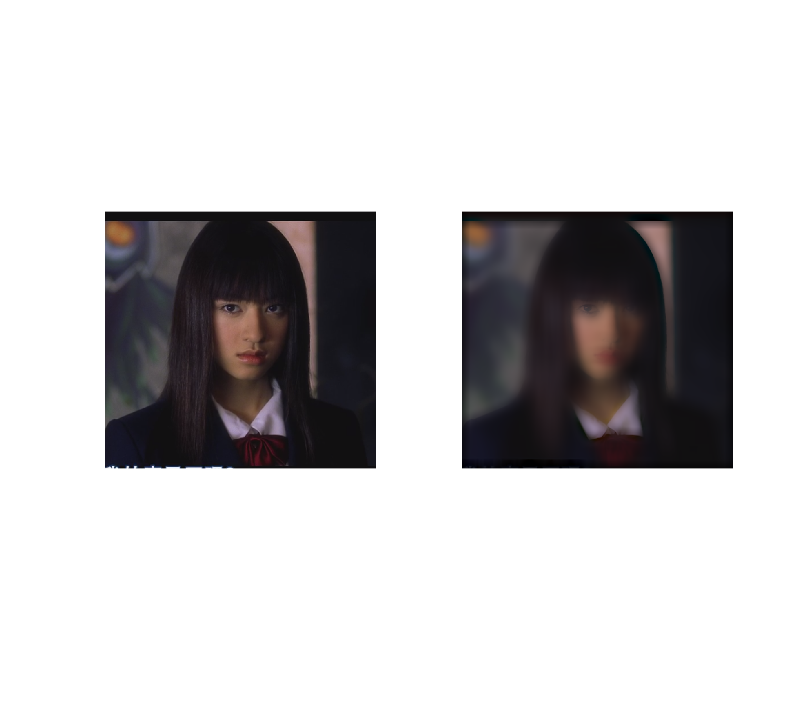

%提示用户选取图片
button=questdlg('hi there! please choose a picture you want to retouch,','WELCOME','OK','QUIT','OK');
switch button
    case 'OK'

%读取图片信息｜呈现原图
[Name, Path] = uigetfile('*.jpg;*.png;*.gif;*.bmp', 'Please Select your picture:');
image_info = [Path Name];
image = imread(image_info);
imshow(image);
[h,w,k]=size(image);

%提示用户选择操作手段
while true
    [select,ok]=listdlg('ListString',{'rotation','extraction','discoloration','negative','retro','dark','shift','sculpture','neon','sketch','wierd','mosaic','dermabrasion'},...
        'PromptString','options','name','select your option','SelectionMode','single');
    if ok==1   
        switch select
            case 1
                % Acquire the rotation angle
                angle_input = inputdlg('Please input the rotation angle (in degrees) in this dialog box:');
                r_deg = str2num(char(angle_input));
                rotate(image,r_deg);
            case 2
                extraction(image)
            case 3
                discoloration(image);
            case 4
                negetive(image);
            case 5
                retro(image, h, w, k);
            case 6
                dark(image, h, w, k);
            case 7
                shift(image); 
            case 8
                sculpture(image);
            case 9
                neon(image);
            case 10
                sketch(image);
            case 11
                weird(image);
            case 12
                mosaic(image);
            case 13
                dermabrasion(image);
        end
        break
    else
        %退出操作提示
        button2=questdlg('Are you sure to leave? ','Quit Warning','YES','NO','NO')
        switch button2
            case 'YES'
                break
            case 'NO'
                %do nothing
        end
    end
end
    case 'QUIT'
end

**旋转图片**

function [rslt] = rotate(img, deg)
     
    % Extract the size of the image
    [x, y, channel] = size(img);
    
    % Calculate the height and width of the image after the rotation
    new_Height = round(x * abs(cosd(deg)) + y * abs(sind(deg)));
    new_Width = round(y * abs(cosd(deg)) + x * abs(sind(deg)));
    
    % Initialize the result matrix
    rslt = ones(new_Height, new_Width, channel) .* 255;
    
    % Three transformational matrices
    % Set the central point of the original image as the origin 
    coord_1 = [1, 0, 0; 0, -1, 0; -0.5 * new_Width, 0.5 * new_Height, 1]; 
    % RRotate the image around the new origin
    rotation = [cosd(deg), -sind(deg), 0; sind(deg), cosd(deg), 0; 0, 0, 1];
    % Reset the origin
    coord_2 = [1, 0, 0; 0, -1, 0; 0.5 * y, 0.5 * x, 1];
    
    % For every point in the original image, conduct the rotation
    for i = 1 : new_Width
        for j = 1 : new_Height
            new_position = [i, j, 1] * coord_1 * rotation * coord_2;
            n = new_position(1, 2); % n corresponds to j, indicating height
            m = new_position(1, 1); % m corresponds to i, indicating width
            n = round(n);
            m = round(m);
            % Check if the point after the rotation i
            if(m >= 1 && m <= y)&&(n >= 1 && n <= x)
                rslt(j, i, :) = img(n, m, :); 
                % Notice that the n/j axis is horizontal and the i/m axis is vertical
            end
        end
    end
    % Output
    rslt = uint8(rslt);
    figure, imshow(rslt);
end



**颜色抓取**

function extraction(image)
% Extract three primary colors by seperating the three channels
R = image(:, :, 1); 
G = image(:, :, 2); 
B = image(:, :, 3);

% Set a threshold value for the extraction
diff_R = 0; 
diff_G = 0; 
diff_B = 0;

% Preparing a gray copy of the image (for later use)
img_gray = rgb2gray(image);

% Extracting red 
% Create a copy of the image
image_R = image;
R_iR = image(:, :, 1); G_iR = image(:, :, 2); B_iR = image(:, :, 3);

% If the difference of R and G/B is bigger than the threshold, extract it
% Notice that the next line illustrates the inverse of the condition of the extraction
condition_r = ~((R - G) > diff_R & (R - B) > diff_R);

% Shift all points whose color is not red to gray
gray_layer_r = img_gray(condition_r);
R_iR(condition_r) = gray_layer_r;
G_iR(condition_r) = gray_layer_r; 
B_iR(condition_r)= gray_layer_r;

%synthesize the new image
image_R(:,:,1) = R_iR; image_R(:,:,2) = G_iR; image_R(:, :, 3) = B_iR;

% Output
figure;
imshow(image_R);

%Extracting green
image_G = image;
R_iG = image(:, :, 1); 
G_iG = image(:, :, 2); 
B_iG=image(:, :, 3);

condition_g = ~((G - R) > diff_G & (G - B) > diff_G);

gray_layer_g = img_gray(condition_g);
R_iG(condition_g) = gray_layer_g; 
G_iG(condition_g) = gray_layer_g; 
B_iG(condition_g) = gray_layer_g;

image_G(:, :, 1) = R_iG; 
image_G(:, :, 2) = G_iG; 
image_G(:, :, 3) = B_iG;

figure;
imshow(image_G);

%Extracting blue
image_B = image;
R_iB = image(:, :, 1);
G_iB = image(:, :, 2);
B_iB = image(:, :, 3);

condition_b = ~((B - R) > diff_B & (B - G) > diff_B); 

gray_layer_b = img_gray(condition_b); 
R_iB(condition_b) = gray_layer_b; 
G_iB(condition_b) = gray_layer_b; 
B_iB(condition_b) = gray_layer_b; 

image_B(:, :, 1) = R_iB; 
image_B(:, :, 2) = G_iB; 
image_B(:, :, 3) = B_iB;

figure;
imshow(image_B);
end

**1号滤镜——黑白**

function img=discoloration(img)
    img= rgb2gray(img);
    img = im2double(img);
    figure; imshow(img);
    colorbar;
end

**2号滤镜——负片**

function img=negetive(img)
    img= rgb2gray(img);
    img = im2double(img);
    imgn=imadjust(img,[0,1],[1,0]);
    figure,imshow(imgn);
    colorbar;
end

**3号滤镜——复古**

function imgn=retro(img, h, w, k)

    R=double(img(:,:,1));
    G=double(img(:,:,2));
    B=double(img(:,:,3));

    rR=R*0.393+G*0.769+B*0.198;
    rG=R*0.349+G*0.686+B*0.168;
    rB=R*0.272+G*0.534+B*0.131;

    randR=rand()*0.5+0.5;
    randG=rand()*0.5+0.5;
    randB=rand()*0.5+0.5;

    imgn=zeros(h,w,k);
    imgn(:,:,1)=randR*rR+(1-randR)*R;
    imgn(:,:,2)=randG*rG+(1-randG)*G;
    imgn(:,:,3)=randB*rB+(1-randB)*B;
    
    figure;imshow(uint8(imgn));
    colorbar;
end

**4号滤镜——暗调**

function imgn=dark(img, h, w, k)

    R=double(img(:,:,1));
    G=double(img(:,:,2));
    B=double(img(:,:,3));
    
    rR=(R .* R / 255);
    rG=(G .* G / 255);
    rB=(B .* B / 255);

    randR=rand()*0.5+0.5;
    randG=rand()*0.5+0.5;
    randB=rand()*0.5+0.5;

    imgn=zeros(h,w,k);
    imgn(:,:,1)=randR*rR+(1-randR)*R;
    imgn(:,:,2)=randG*rG+(1-randG)*G;
    imgn(:,:,3)=randB*rB+(1-randB)*B;
    
    figure;imshow(uint8(imgn));
    colorbar;
end


**5号滤镜——移色**

function imgn=shift(img)

    R=double(img(:,:,1));
    G=double(img(:,:,2));
    B=double(img(:,:,3));
    
    R(:,1:245)=R(:,12:256);
    B(:,12:256)=B(:,1:245);
    
    img2=img;
    img2(:,:,1)=R;
    img2(:,:,2)=G;
    img2(:,:,3)=B;
    imgn = imadd(img*0.5,img2*0.5);
    figure;imshow(uint8(imgn));
    colorbar;
end

**浮雕**

I(i,j) = I(i,j) - I(i.j+1) + B

function sculpture(image)

B = 100;

I_Gray = rgb2gray(image);
[h,w] = size(I_Gray);
I_New = zeros(h,w);
I_New(:,1:end-1) = I_Gray(:,2:end);
I_New = min(I_Gray-uint8(I_New)+B,255);
subplot(1,2,1);
imshow(image);
subplot(1,2,2);
imshow(I_New);
end

霓虹

c=2*(c1+c2)^0.5   c1为该像素点与同行右侧像素差的平方，c2为该像素与同列下侧像素差的平方

function neon(image)

[h_2,w_2,c] = size(image);
M_1 = zeros(h_2,w_2,c);
M_2 = zeros(h_2,w_2,c);
M_1(1:end-1,:,:) = image(2:end,:,:);
M_2(:,1:end-1,:) = image(:,2:end,:);
I2_New = min(2*((double(image)-M_1).^2+(double(image)-M_2).^2).^0.5,255);
subplot(1,2,1);
imshow(image);
subplot(1,2,2);
imshow(uint8(I2_New));
end

素描

1.图像去色得A 2.取反得B 3.对取反图像模糊处理 4图像叠加 A+(A*B)/(256-B)

function sketch(image)
[h_2,w_2,c] = size(image);
I2_N = zeros(h_2,w_2);
I2_Gray = rgb2gray(image);
I2_G = 255-I2_Gray;
Data = [1,2,1;1,4,1;1,2,1];
for i=2:h_2-1
    for j=2:w_2-1
        M = Data.*double(I2_G(i-1:i+1,j-1:j+1));
        I2_N(i,j) = sum(M(:))/16;
    end
end
I2_Gray = double(I2_Gray);
I2_N = double(I2_N);
I2_New = uint8(min(I2_Gray+(I2_Gray.*I2_N)./(256-I2_N),255));
subplot(1,2,1);
imshow(image);
subplot(1,2,2);
imshow(I2_New);
end

色彩特效(诡异版）

function weird(image)
[w_3,h_3,c] = size(image);
%碧绿 r=(g-b)^2/128 g=(r-b)^2/128 b=(r-g)^2/128
M = zeros(w_3,h_3,c);
M2 = zeros(w_3,h_3,c);
M(:,:,1) = image(:,:,2);
M(:,:,2) = image(:,:,1);
M(:,:,3) = image(:,:,1);
M2(:,:,1) = image(:,:,3);
M2(:,:,2) = image(:,:,3);
M2(:,:,3) = image(:,:,2);
I3_New = uint8(min((M-M2).^2./128,255));
subplot(2,2,1);
imshow(image);
subplot(2,2,2);
imshow(I3_New);
%冰冻 r = |r-g-b|*3/2,g/b同理
M(:,:,2) = image(:,:,3);
M2(:,:,2) = image(:,:,1);
I3_New = uint8(min(abs(double(image)-M-M2)*3/2,255));
subplot(2,2,3);
imshow(I3_New);
%熔铸 r=128*r/(g+b+1),g/b同理
I3_New = uint8(min(double(image)*128./(M+M2+1),255));
subplot(2,2,4);
imshow(I3_New);
end

马赛克

将一个小方格内所有像素点用原方格像素平均值代替

function mosaic(image)

I4_New = image;
[h_4,w_4,c] = size(image);
h1 = 30;
h2 = 150;
w1 = 150;
w2 = 300;
r = 10;
h2 = min(h2,h_4);
w2 = min(w2,w_4);
n = r*r;
for c = 1:3
    for w = w1+r:r:w2
        for h = h1+r:r:h2
            M = I4_New(h-r:h,w-r:w,c);
            I4_New(h-r:h,w-r:w,c) = sum(M(:))/n;
        end
    end
end
subplot(1,2,1);
imshow(image);
subplot(1,2,2);
imshow(I4_New);
end

磨皮

高斯滤波

function dermabrasion(image)

I5_New = image;
r = 20;
Y = 100;
M = zeros(2*r+1,2*r+1);
[h_5,w_5,C] = size(image);
for c=1:3
    for h=1:h_5
        for w=1:w_5
            h1 = max(h-r,1);
            h2 = min(h+r,h_5);
            w1 = max(w-r,1);
            w2 = min(w+r,w_5);
            M(1:h2-h1+1,1:w2-w1+1) = 1 - double(abs(image(h1:h2,w1:w2,c) - image(h,w,c)))/Y;
            M2 = M(1:h2-h1+1,1:w2-w1+1).*double(image(h1:h2,w1:w2,c));
            I5_New(h,w,c) = floor(sum(M2(:))/sum(M(:)));
        end
    end  
end
subplot(1,2,1);
imshow(image);
subplot(1,2,2);
imshow(I5_New);
end